clear, clc;

% change current folder to wherever your git repos are;
% this will include the templates folder, with the code the professor
% provided us
addpath(".\RBE502-Quadrotor\", ".\RBE502-Quadrotor\templates\");

% initial conditions (State Vector)
z0 = zeros(12,1);   % z is the state vector (?)

r = [0; 0; 0];  % External Forces
n = [0; 0; 0];  % Moment Vector
%u = [1; 0.9; 1.9; 1.5];
u = [1; 0.9; 1.9; 1.5]; % rotor/motor inputs (?)

qr = QuadrotorClass(z0, r, n, u);

t = linspace(0, 3, 200);

[t, z] = ode45(@(t,z) quadrotor(t,z,qr.u,qr.p,qr.r,qr.n), t, z0);

qr.plotResults(t, z);

## Animation

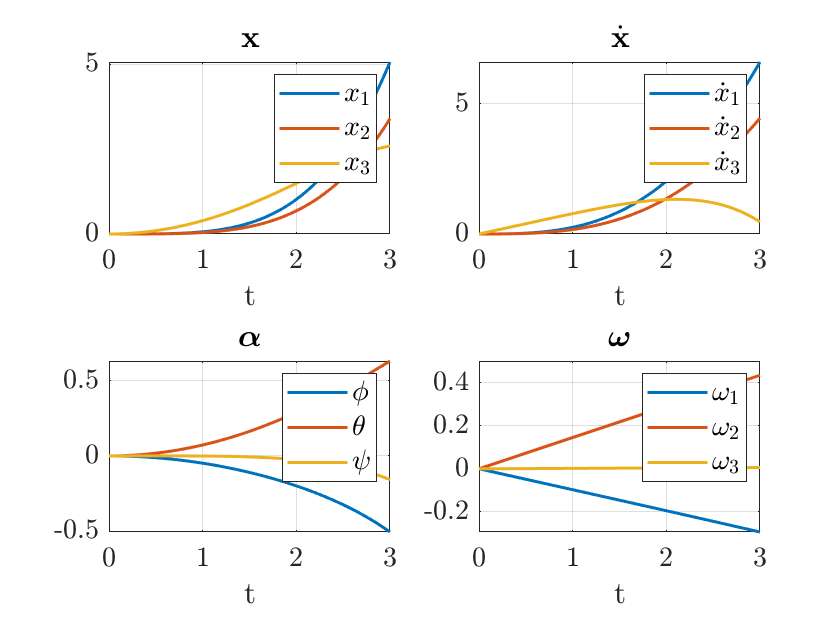

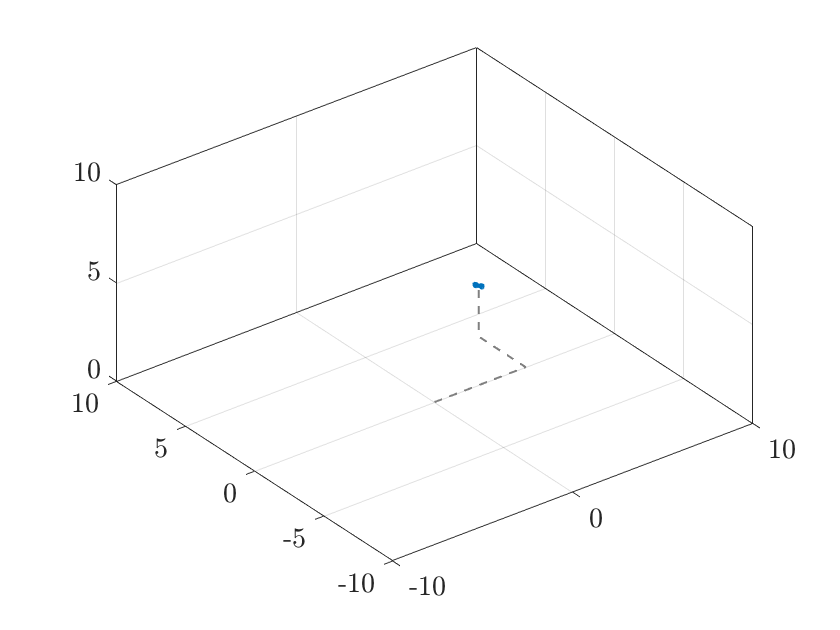

animation_fig = figure;

airspace_box_length = 10;

animation_axes = axes('Parent', animation_fig,...
    'NextPlot','add','DataAspectRatio',[1 1 1],...
    'Xlim',airspace_box_length*[-1.0 1.0],...
    'Ylim',airspace_box_length*[-1.0 1.0],...
    'Zlim',airspace_box_length*[0 1],...
    'box','on','Xgrid','on','Ygrid','on','Zgrid','on',...
    'TickLabelInterpreter','LaTeX','FontSize',14);

view(animation_axes, 3);

N = 10;
Q = linspace(0,2*pi,N)';
circle = 0.3*qr.l*[cos(Q) sin(Q) zeros(N,1)];
loc = qr.l*[1 0 0; 0 1 0; -1 0 0; 0 -1 0];


silhouette = plot3(0,0,0, '--', 'Color', 0.5*[1 1 1], 'LineWidth', 1 ,...
    'Parent', animation_axes);
body = plot3(0,0,0, 'Color',lines(1), 'LineWidth', 2,...
        'Parent', animation_axes);
for i=1:4
    rotor(i) = plot3(0,0,0, 'Color', lines(1), 'LineWidth', 2,...
        'Parent', animation_axes);
end

tic;
for k=1:length(t)
    
    R = [ cos(z(k,5))*cos(z(k,6)), sin(z(k,4))*sin(z(k,5))*cos(z(k,6)) - cos(z(k,4))*sin(z(k,6)), sin(z(k,4))*sin(z(k,6)) + cos(z(k,4))*sin(z(k,5))*cos(z(k,6));
          cos(z(k,5))*sin(z(k,6)), cos(z(k,4))*cos(z(k,6)) + sin(z(k,4))*sin(z(k,5))*sin(z(k,6)), cos(z(k,4))*sin(z(k,5))*sin(z(k,6)) - sin(z(k,4))*cos(z(k,6));
                     -sin(z(k,5)),                                 sin(z(k,4))*cos(z(k,5)),                                 cos(z(k,4))*cos(z(k,5))];
    for i=1:4
        ctr(i,:) = z(k,1:3) + loc(i,:)*R';
        pose = ones(N,1)*z(k,1:3) + (ones(N,1)*loc(i,:) + circle)*R';
        set(rotor(i), 'XData', pose(:,1), 'YData', pose(:,2),  'ZData', pose(:,3) );
         
    end
    set(silhouette,'XData', [0, z(k,1), z(k,1), z(k,1)],...
        'YData', [0, 0, z(k,2), z(k,2)],...
        'ZData', [0, 0, 0, z(k,3)]);
    set(body, 'XData', [ctr([1 3],1); NaN; ctr([2 4],1)], ...
        'YData', [ctr([1 3],2); NaN; ctr([2 4],2)],...
        'ZData', [ctr([1 3],3); NaN; ctr([2 4],3)] );
    pause(t(k)-toc);
    pause(0.01);
end